% Lire le fichier CSV
supply_results = readtable('supply_results_SYDNEY.csv'); 

reliability = readtable('reliability_results_SYDNEY.csv');

overflow = readtable("overflow_results_SYDNEY.csv");

daily_results = readtable("daily_results_SYDNEY.csv");


% Afficher les noms de colonnes
disp('Colonnes de supply_results :');

Colonnes de supply_results :


disp(supply_results.Properties.VariableNames);

    {'StorageCapacity'}    {'failed_max_'}    {'failed_average_'}    {'unmet_max_'}    {'unmet_average_'}    {'met_max_'}    {'met_average_'}




disp('Colonnes de reliability :');

Colonnes de reliability :


disp(reliability.Properties.VariableNames);

    {'StorageCapacity'}    {'TemporalReliability'}    {'VolumetricReliability'}    {'OverflowFraction'}    {'TotalFailure_fraction_'}




disp('Colonnes de overflow :');

Colonnes de overflow :


disp(overflow.Properties.VariableNames);

    {'StorageCapacity'}    {'Streak_max_'}    {'Streak_average_'}    {'Volume_max_'}    {'Volume_average_'}




disp('Colonnes de daily_results :');

Colonnes de daily_results :


disp(daily_results.Properties.VariableNames); 

    {'Day'}    {'Tanksize'}    {'StorageVolume'}    {'ServedVolume'}    {'OverflowVolume'}



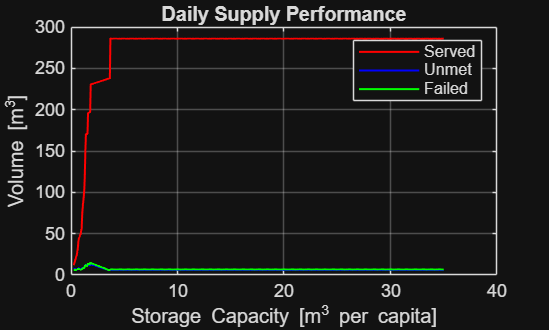



% --- SUPPLY RESULTS ---
figure;
plot(supply_results.StorageCapacity, supply_results.met_average_, '-r', 'LineWidth', 1.0);
hold on;
plot(supply_results.StorageCapacity, supply_results.unmet_average_, '-b', 'LineWidth', 1.0);
plot(supply_results.StorageCapacity, supply_results.failed_average_, '-g', 'LineWidth', 1.0);
xlabel('Storage Capacity [m^3 per capita]');
ylabel('Volume [m^3]');
title('Daily Supply Performance');
legend('Served', 'Unmet', 'Failed');
grid on;

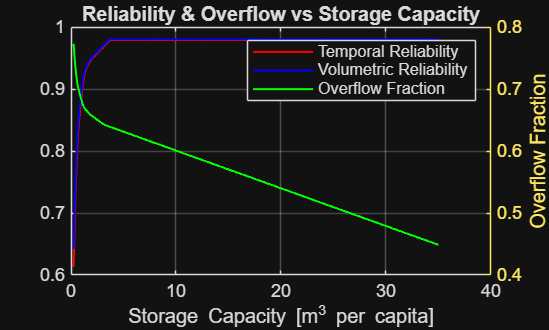


% --- RELIABILITY RESULTS ---
figure;
plot(reliability.StorageCapacity, reliability.TemporalReliability, '-r', 'LineWidth', 1.0);
hold on;
plot(reliability.StorageCapacity, reliability.VolumetricReliability, '-b', 'LineWidth', 1.0);
yyaxis right
plot(reliability.StorageCapacity, reliability.OverflowFraction, '-g', 'LineWidth', 1.0);
ylabel('Overflow Fraction');
xlabel('Storage Capacity [m^3 per capita]');
title('Reliability & Overflow vs Storage Capacity');
legend('Temporal Reliability', 'Volumetric Reliability', 'Overflow Fraction');
grid on;

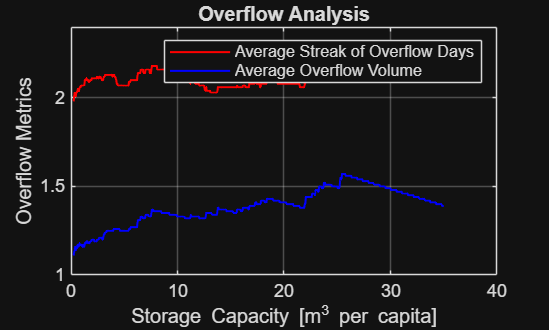


% --- OVERFLOW RESULTS ---
figure;
plot(overflow.StorageCapacity, overflow.Streak_average_, '-r', 'LineWidth', 1.0);
hold on;
plot(overflow.StorageCapacity, overflow.Volume_average_, '-b', 'LineWidth', 1.0);
xlabel('Storage Capacity [m^3 per capita]');
ylabel('Overflow Metrics');
title('Overflow Analysis');
legend('Average Streak of Overflow Days', 'Average Overflow Volume');
grid on;

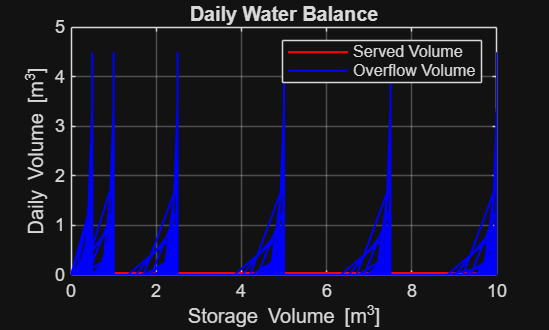


% --- DAILY RESULTS ---
figure;
plot(daily_results.StorageVolume, daily_results.ServedVolume, '-r', 'LineWidth', 1.0);
hold on;
plot(daily_results.StorageVolume, daily_results.OverflowVolume, '-b', 'LineWidth', 1.0);
xlabel('Storage Volume [m^3]');
ylabel('Daily Volume [m^3]');
title('Daily Water Balance');
legend('Served Volume', 'Overflow Volume');
grid on;